## Intro

In this scrip, i adapt the fv5 and no longer needs to adjust the experiment number N according to the residual. For example, if gradient (in one direction) is about 1e-25m^4, we should let the error less than 1e-26m^4.

Making test by scrip 'parameter_selecting_error_estimation', we got data. Now i suppose we need 1000 simulation to get error approx to 1e10nm^4.

We uses 4 parameters: m, zeta, psi and H. 

## Import data and previewing

figure
data_name='p47_5s'

data_name = 'p47_5s'

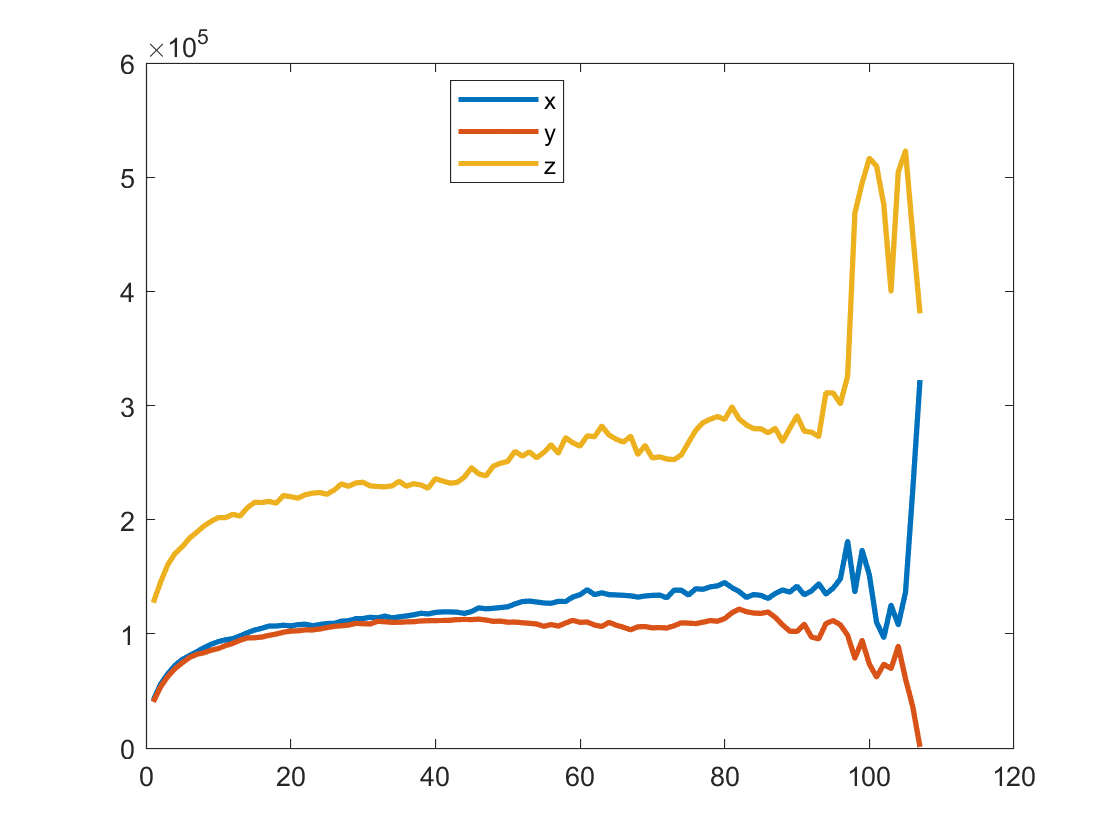

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
plot(MSD_p47_5s_All.MSD_PP,'LineWidth',2)
legend('x','y','z','Location',"best");

 cut down the declining part, we delete all data after the maximum one.

experiment_interval=5

experiment_interval = 5

%x:1, y:2, z:3
selecting_xyz=3;
Reserved_length=find(MSD_p47_5s_All.MSD_PP(:,selecting_xyz)==max(MSD_p47_5s_All.MSD_PP(:,selecting_xyz)));
interceptive_experiment_MSD=1e-18*MSD_p47_5s_All.MSD_PP(1:Reserved_length,selecting_xyz);

## Data Importing

import time settings

% import Time interval
delta=0.1;

Initilizing parameters

% input the initial parameter

input=[3e-09,0.2,2e-08,0.74];
m_0=input(1);
psi_0=input(2);
zeta_0=input(3);
H_0=input(4);

% put it in use

m=m_0

m = 3.0000e-09

psi=psi_0

psi = 0.2000

zeta=zeta_0

zeta = 2.0000e-08

H=H_0

H = 0.7400


% decide step length and sample length (proportional)

step_length=1/50;
sample_length=1/50;

%setting stopping condition
residual_limit=1e-25;

%importing (N/1000)^0.5*error=sqrN_1000_error(error/m^4)
sqrN_1000_error=1e-26;

## storage system

% add parameter history and gradient history
parmeter_history=[m,psi,zeta,H];
gradient_history=[];
residual_history=[];
N_history=[];

## Main loop

%% Calculating decline in three direction
% 
step_number=0;
Total_experiment_number=100;%initializtion
while true
    step_number=step_number+1
    disp(['------step',num2str(step_number),' N= ',num2str(Total_experiment_number),'--------'])
    residual_0=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m,delta,Total_experiment_number);
    if step_number>1
        if residual_0>residual_history(end,1)%if there is bad residual, we just get back and try another time
            m=parameter_history(end-1,1);
            psi=parameter_history(end-1,2);
            zeta=parameter_history(end-1,3);
            H=parameter_history(end-1,4);
            parmeter_history=parmeter_history(1:end-1);
            gradient_history=gradient_history(1:end-1);
            residual_history=residual_history(1:end-1);
            continue
            end
    end
    residual_m=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m*(1+sample_length),delta,Total_experiment_number);
    residual_psi=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi*(1+sample_length),zeta,H,m,delta,Total_experiment_number);
    residual_zeta=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta*(1+sample_length),H,m,delta,Total_experiment_number);
    residual_H=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H*(1+sample_length),m,delta,Total_experiment_number);
    gradient=[residual_m-residual_0,residual_psi-residual_0,residual_zeta-residual_0,residual_H-residual_0]/sample_length;
    delta_min=min(gradient)*sample_length;
    unit_gradient=gradient/norm(gradient);
    if step_number==1
        standard_gradient=norm(gradient);
    end
%% 
% make new parameter in the opposute direction of gradient
    por=norm(gradient)/standard_gradient;
    m=m*(1-unit_gradient(1)*step_length*por)
    psi=psi*(1-unit_gradient(2)*step_length*por)
    zeta=zeta*(1-unit_gradient(3)*step_length*por)
    H=H*(1-unit_gradient(4)*step_length*por)
    parmeter_history=[parmeter_history;[m,psi,zeta,H]];
    gradient_history=[gradient_history;gradient];
    residual_history=[residual_history;[residual_0,Total_experiment_number]];
    disp(['residual = ',num2str(residual_0),', N = ',num2str(Total_experiment_number)])
    %end or not?
    if residual_0<=residual_limit
        break
    end
    
    %changing N
    Total_experiment_number=max(floor((sqrN_1000_error/delta_min*10)^2*1000),100);
end

step_number = 1

------step1--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 3.0361e-09

psi = 0.2024

zeta = 2.0210e-08

H = 0.7416

residual = 1.7906e-24, N = 100


step_number = 2

------step2--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 3.0398e-09

psi = 0.2018

zeta = 2.0048e-08

H = 0.7321

residual = 1.2858e-24, N = 100


step_number = 3

------step3--------


## saving

saving data

saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.02图像';
save([saving_location,'\data\history data N=',num2str(Total_experiment_number),' step=',num2str(step_length),datestr(now,' yyyy-mm-dd HH'),'.mat'],'parmeter_history','gradient_history','residual_history')

Plot and plot saving: gradient history

figure
plot((residual_history(:,1))*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['first step=',num2str(step_length),' N=',num2str(Total_experiment_number)],[' standard gradient=',num2str(standard_gradient)]},'Color','r','FontSize',15)

% saving
saveas(gcf,[saving_location,'\image\residual history image N=',num2str(Total_experiment_number),' step=',num2str(step_length),' ',datestr(now,'yyyy-mm-dd HH'),'.png'])